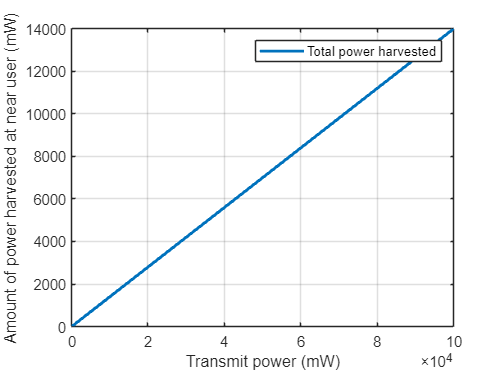

clc; clear variables; close all;

 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 1;   %Source to near user distance    
dsf = 9;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn =  (randn(1,N)+1i*randn(1,N))/sqrt(2) ;
gsn = ((abs(hsn)).^2);
hsf =  (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = ((abs(hsf)).^2);
hnf =  (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = ((abs(hnf)).^2);



Pt = 10:5:50;    % 发送功率（dBm）
pt =  10.^(Pt/10);    % 发送功率（线性尺度）mW
B = 1000000;             %bandwidth 1 MHz (or 200kHz)
N0_dBm=-60;                % Noise special density  (in dBm/Hz)
N0=10^(N0_dBm/10)*B;          % Linear noise in mW
snr = pt/N0;       %SNR in linear
SNR = 10*log10(snr);%SNR in dB

%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0.4; %power splitting coefficient
del = 10^-6; %a small number

%Some buffers
pn = zeros(1,length(pt));
pf = zeros(1,length(pt));

cn = zeros(1,length(pt));
cf = zeros(1,length(pt));
cph = zeros(1,length(pt));
rsum = zeros(1,length(pt));

for u = 1:length(pt)    
    %frac =  max(0, (1 - t1*(1+dsn^eta)./(snr(u)*(af - t1*an)*gsn)));
    

    %Amount of power harvested by near user
    ph = pt(u)*gsn.*frac*eff/(1+dsn^eta);
    

    %SNIR for each user
    SNRnf = af*snr(u)*(1-frac).*gsn./(snr(u).*(an*(1-frac).*gsn) + (1+dsn^eta));
    SNRnf1 = af*snr(u).*gsn./(snr(u).*(an*gsn) + (1+dsn^eta));
    SNRnn = an*snr(u)*(1-frac).*gsn/(1+dsn^eta);
    SNRsf = af*snr(u).*gsf./(snr(u).*an.*gsf+(1+dsf^eta));
    SNRfmrc = SNRsf + (eff*snr(u).*gnf.*frac.*gsn./((1+dsn^eta)*(1+dnf^eta)));

    %Achievable rate of near user
    Rnf = 0.5 *log2(1 + SNRnf);
    Rnn = 0.5 *log2(1 + SNRnn);
    Rnf1 = 0.5 * log2(1 + SNRnf1);
    %Achievable rate of far user
    Rf = 0.5 *log2(1 + SNRfmrc);
    Rsf = 0.5*log2(1 + SNRsf);
    cn(u) = mean(Rnn);
    cf(u) = mean(Rf);
    cph(u) = mean(ph);
    rsum(u) = cn(u) + cf(u);
    
    for k=1:N
       if (  Rf(k)<R1) &&(Rnf(k)>R1)
          pf(u) = pf(u) + 1;
       end
        if (Rsf(k) < R1)&&(Rnf(k)<R1)
          pf(u) = pf(u) + 1;
        end
        if Rnf1(k)<R1 
          pn(u) = pn(u) + 1;
       end
        if (Rnf1(k) > R1)&&(Rnn(k)<R2)
          pn(u) = pn(u) + 1;
       end

    end

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);

figure;
plot(pt, cph, 'linewidth', 2); hold on; grid on;
legend('Total power harvested');
xlabel('Transmit power (mW)');
ylabel('Amount of power harvested at near user (mW)');

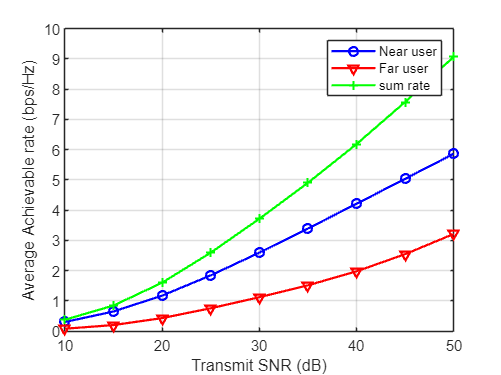


figure;
plot(Pt, cn, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
plot(Pt, cf, 'r-v', 'LineWidth', 1.5, 'MarkerSize', 6);
plot(Pt, rsum, 'g-+', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('Near user','Far user','sum rate');
xlabel('Transmit SNR (dB)');
ylabel('Average Achievable rate (bps/Hz)');

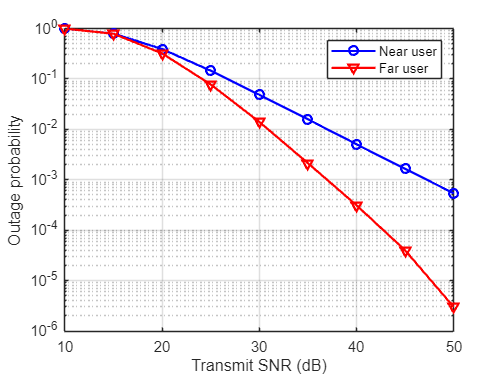


figure;
semilogy(SNR, poutn1, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
semilogy(SNR, poutf1, 'r-v', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('Near user','Far user');
xlabel('Transmit SNR (dB)');
ylabel('Outage probability');